## global body planner test

addpath(genpath('fpp_planner\'));
addpath(genpath('math\'));
x_init = [0;0;0; 0;0;0.3];
vel_tar = [0;0;0.05; 1;0;0];
horizon_num = 200;
dt = 0.05;
[state_traj] = body_traj_planner(x_init ,vel_tar, horizon_num, dt)

state_traj =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      

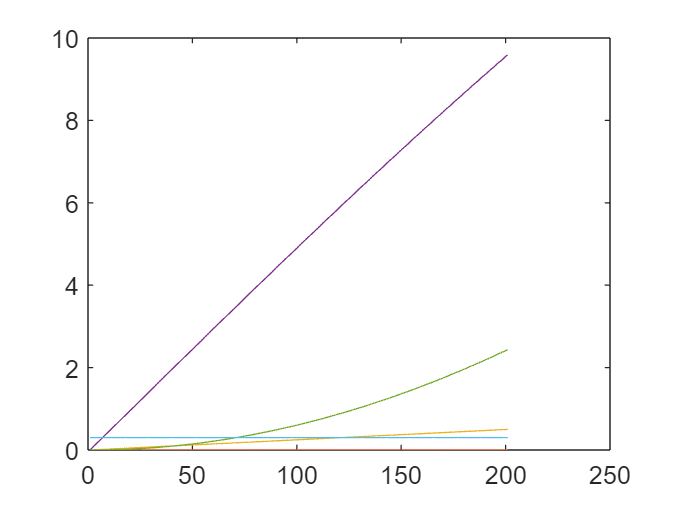


for i=1:6
plot(state_traj(i,:))
hold on
end

## local swing foot planner test

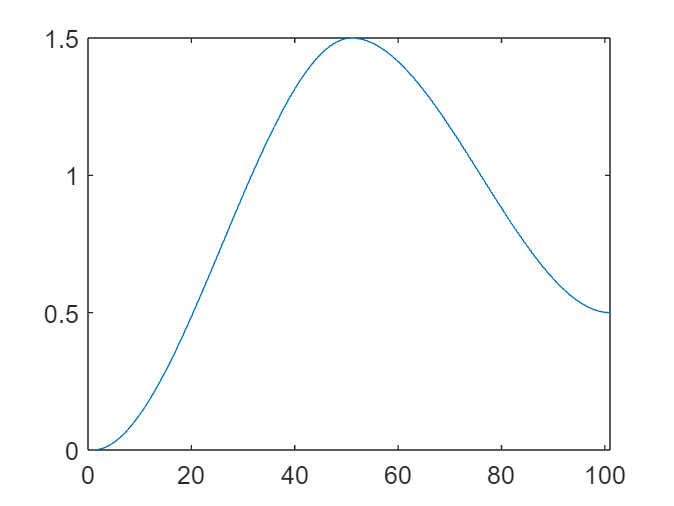

addpath(genpath('fpp_planner\'));
p_start = [-1;-1;0];
p_end = [1;1;0.5];
fp_h = 1.5;
fpp_arr = [];

for t_sw = 0:0.01:1
    fpp_t = swing_fpp_planner(p_start,p_end,fp_h,t_sw);
    fpp_arr = [fpp_arr, fpp_t];
end

clf;
plot(fpp_arr(3,:));

## stance fpp planner

addpath(genpath('fpp_planner\'));
addpath(genpath('math\'));

[world_p, body_p, ctr_p, path]...
    = hardware_params();

x_init = [0;0;0; 0;0;0.3];
vel_tar = [0;0;0.05; 1;0;0];
horizon_num = ctr_p.mpc_horizon_steps;
dt_mpc = ctr_p.dt_mpc;

[state_traj] = body_traj_planner(x_init ,vel_tar, horizon_num, dt_mpc)

state_traj =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      


[ref_fpp_traj, ref_contact_event]...
    = stance_fpp_planner(state_traj, vel_tar, world_p, body_p, ctr_p)

calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp
calc next fpp


ref_fpp_traj =     0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1700    0.1400    0.1492    0.1756    0.2173    0.2724    0.3389    0.4149    0.4986    0.5881    0.6813    0.7765    0.8716    0.9648    1.0543    1.1380    1.2140    1.2805    1.3356    1.3773    1.4037    1.4129    1.4129    1.4129    1.4129    1.4129    1.4129    1.4129    1.4129    1.4129    1.4129
    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1300    0.1302    0.1310    0.1321    0.1336    0.1354    0.1374    0.1397    0.1421    0.1446    0.1472    0.1497    0.1523    0.1547    0.1569    0.1590    0.1608    0.1623    0.1634    0.1641    0.1644    0.1644    0.1644    0.1644    0.1644    0.1644    0.1644    0.1644    

ref_contact_event =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     1     1     